# **Движение звезд**

close all
clear variables

## **Импорт данных**

spectra = importdata('spectra.csv')

spectra = 	1.0e+-12 *

    0.3088    0.1340    0.0598    0.0892    0.1088    0.1625    0.0392
    0.3136    0.1338    0.0607    0.0898    0.1084    0.1630    0.0382
    0.3105    0.1347    0.0618    0.0915    0.1104    0.1615    0.0371
    0.3076    0.1357    0.0625    0.0931    0.1124    0.1586    0.0378
    0.3088    0.1354    0.0627    0.0936    0.1122    0.1574    0.0391
    0.3105    0.1343    0.0622    0.0932    0.1136    0.1589    0.0396
    0.3122    0.1335    0.0619    0.0929    0.1138    0.1611    0.0402
    0.3101    0.1325    0.0620    0.0925    0.1130    0.1607    0.0399
    0.3078    0.1335    0.0626    0.0924    0.1124    0.1593    0.0387
    0.3047    0.1329    0.0625    0.0918    0.1108    0.1582    0.0379


lambdaStart = importdata('lambda_start.csv')

lambdaStart = 630.0200

lambdaDelta = importdata('lambda_delta.csv')

lambdaDelta = 0.1400

starNames = importdata('star_names.csv')

starNames = 7×1 cell array
    {'HD30584'  }
    {'HD10032'  }
    {'HD64191'  }
    {'HD5211'   }
    {'HD56030'  }
    {'HD94028'  }
    {'SAO102986'}


## **Константы**

lambdaPr = 656.28 %нм

lambdaPr = 656.2800

speedOfLight = 299792.458 %км/с

speedOfLight = 2.9979e+05

## Определение диапазона длин волн

count_obs = size(spectra, 1) %количество наблюдений

count_obs = 357

count_stars = size(starNames, 1) %количество звезд

count_stars = 7

lambdaEnd = lambdaStart + (count_obs - 1) * lambdaDelta

lambdaEnd = 679.8600

lambda = (lambdaStart : lambdaDelta: lambdaEnd)'

lambda =   630.0200
  630.1600
  630.3000
  630.4400
  630.5800
  630.7200
  630.8600
  631.0000
  631.1400
  631.2800


## Расчет скоростей удаления для каждой из звезд и построение графика

speed = zeros(count_stars, 1) 

speed =      0
     0
     0
     0
     0
     0
     0



fg1 = figure

fg1 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [404 247 560 420]
       Units: 'pixels'

  Show all properties



for i = 1:count_stars
    s = spectra(:, i)
    [sHa, idx] = min(s)
    lambdaHa = lambda(idx)    

    z = lambdaHa/lambdaPr - 1
    speed_star = z * speedOfLight    
    speed(i) = speed_star

    if speed(i) > 0
        plot(lambda, s, "LineWidth", 3)
    else
        plot(lambda, s, '--', "LineWidth", 1)
    end
    hold on    
end

s = 	1.0e+-12 *

    0.3088
    0.3136
    0.3105
    0.3076
    0.3088
    0.3105
    0.3122
    0.3101
    0.3078
    0.3047


sHa = 1.6340e-13

idx = 188

lambdaHa = 656.2000

z = -1.2190e-04

speed_star = -36.5445

speed =   -36.5445
         0
         0
         0
         0
         0
         0


s = 	1.0e+-12 *

    0.1340
    0.1338
    0.1347
    0.1357
    0.1354
    0.1343
    0.1335
    0.1325
    0.1335
    0.1329


sHa = 7.2400e-14

idx = 187

lambdaHa = 656.0600

z = -3.3522e-04

speed_star = -100.4973

speed =   -36.5445
 -100.4973
         0
         0
         0
         0
         0


s = 	1.0e+-13 *

    0.5981
    0.6074
    0.6176
    0.6252
    0.6271
    0.6221
    0.6192
    0.6200
    0.6261
    0.6249


sHa = 3.1440e-14

idx = 188

lambdaHa = 656.2000

z = -1.2190e-04

speed_star = -36.5445

speed =   -36.5445
 -100.4973
  -36.5445
         0
         0
         0
         0


s = 	1.0e+-13 *

    0.8919
    0.8981
    0.9152
    0.9311
    0.9355
    0.9321
    0.9286
    0.9247
    0.9240
    0.9177


sHa = 5.3640e-14

idx = 189

lambdaHa = 656.3400

z = 9.1424e-05

speed_star = 27.4083

speed =   -36.5445
 -100.4973
  -36.5445
   27.4083
         0
         0
         0


s = 	1.0e+-12 *

    0.1088
    0.1084
    0.1104
    0.1124
    0.1122
    0.1136
    0.1138
    0.1130
    0.1124
    0.1108


sHa = 6.8980e-14

idx = 189

lambdaHa = 656.3400

z = 9.1424e-05

speed_star = 27.4083

speed =   -36.5445
 -100.4973
  -36.5445
   27.4083
   27.4083
         0
         0


s = 	1.0e+-12 *

    0.1625
    0.1630
    0.1615
    0.1586
    0.1574
    0.1589
    0.1611
    0.1607
    0.1593
    0.1582


sHa = 9.8010e-14

idx = 191

lambdaHa = 656.6200

z = 5.1807e-04

speed_star = 155.3139

speed =   -36.5445
 -100.4973
  -36.5445
   27.4083
   27.4083
  155.3139
         0


s = 	1.0e+-13 *

    0.3918
    0.3821
    0.3712
    0.3776
    0.3910
    0.3955
    0.4023
    0.3986
    0.3874
    0.3793


sHa = 2.2140e-14

idx = 185

lambdaHa = 655.7800

z = -7.6187e-04

speed_star = -228.4029

speed =   -36.5445
 -100.4973
  -36.5445
   27.4083
   27.4083
  155.3139
 -228.4029


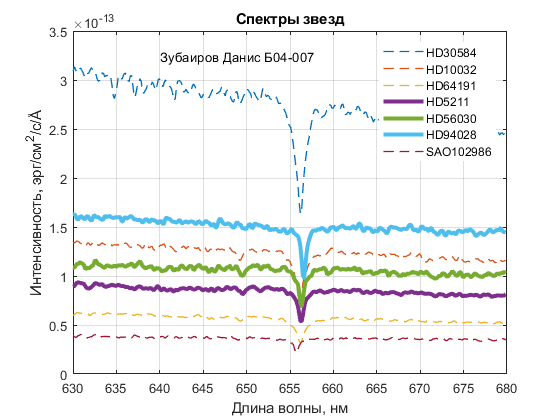


set(fg1, 'Visible', 'on')
grid on
xlabel('Длина волны, нм')
ylabel(['Интенсивность, эрг/см^2/с/', char(197)])
title({'Спектры звезд'})
legend(starNames)
text(lambdaStart + 10, 3.25 * 10^-13,  'Зубаиров Данис Б04-007')
hold off 

saveas(fg1, 'spectra.png')

## Создание вектора movaway 

movaway = starNames((speed)' > 0)

movaway = 3×1 cell array
    {'HD5211' }
    {'HD56030'}
    {'HD94028'}
